# Lattice Modulation, Scan Force, real pulse sequence

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(linspace(1.164173e-2,1.3407113e-2,100));
% bList = {-1.2e-2};
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

% set laser
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = {laser};

% set optical lattice
ol = OpticalLattice(atom,laser{1});
ol.DepthSpec = 8.5174 * ol.RecoilEnergy;
ol.updateIntensity;
kL = ol.Laser.AngularWavenumber;
laser = {ol.Laser};


% set modulation
pulse1 = TrapezoidalSinePulse( ...
    amplitude=0.035 * 4 * 2, ...
    duration=5e-3, ...
    frequency=121e3, ...
    startTime=0,riseTime=1e-4,fallTime=1e-4);
pulse2 = TrapezoidalSinePulse( ...
    amplitude=0.035 * 2, ...
    duration=8e-3, ...
    frequency=143.2231e3, ...
    startTime=5e-3,riseTime=1e-4,fallTime=1e-4);
latticeMod = WaveformList("LatticeMod");
latticeMod.WaveformOrigin = {pulse1,pulse2};
latticeMod.ConcatMethod = "Simultaneous";
% latticeMod.SamplingRate = 10e6;
latticeMod = {latticeMod};

% Initial condition
ic = InitialCondition("LatticeFourierSeSim1D");

ans =   DynamicProperty with properties:

                    Name: 'QuasiMomentum'
             Description: ''
     DetailedDescription: ''
               GetAccess: 'public'
               SetAccess: 'public'
               Dependent: 0
                Constant: 0
                Abstract: 0
               Transient: 0
                  Hidden: 0
           GetObservable: 0
           SetObservable: 0
                AbortSet: 0
             NonCopyable: 1
    PartialMatchPriority: 1
               GetMethod: []
               SetMethod: []
              HasDefault: 0
              Validation: [0×0 meta.Validation]
           DefiningClass: [0×0 meta.class]


% ic.QuasiMomentum = 0.7 * kL;
ic.QuasiMomentum = -kL;
[~,ic.WaveFunction] = ol.computeBand1D(ic.QuasiMomentum,0);


se = LatticeFourierSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = latticeMod,...
    timeStep=1e-7,...
    totalTime=13e-3,...
    initialCondition = ic);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.


se.SavePeriod = 1e4;

se.start

Updating the object file.


## Plot

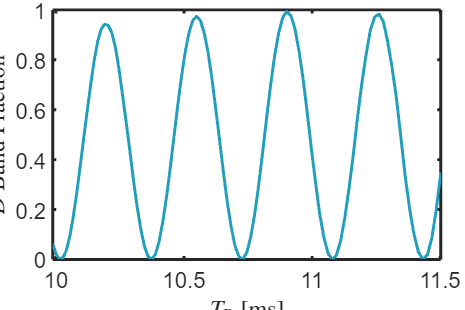

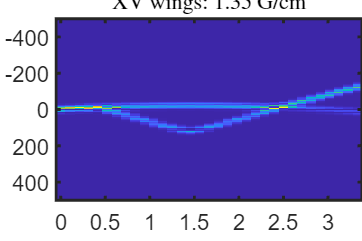

Unrecognized method, property, or field 'SpaceList' for class 'LatticeFourierSeSim1DRun'.

% plot benchmark
trialNumber = 32;
obj = loadTrial(createReader("simulation"),"lattice_fourier_simulation_1d",trialNumber);
data = obj.readBand(2);

mp = MagneticPotential(atom,bField{1});
stateIdx = mp.StateIndex;
stateList = atom.(mp.Manifold).StateList;
mJ = stateList.MJ(stateIdx);
gJ = stateList.gJ(stateIdx);
mI = stateList.MI(stateIdx);
gI = stateList.gI(stateIdx);
muB = Constants.SI("muB");
h = Constants.SI("hbar") * 2 * pi;
hbar = Constants.SI("hbar");
prefactor = (mJ * gJ + mI * gI) * muB / h;
FList0 = abs(h * prefactor * cell2mat(bList));
g = 9.81;
M = atom.mass;
a = laser{1}.Wavelength/2;
% a = obj.Laser{1}.Wavelength/2;
h = Constants.SI('hbar')*2*pi;
fB = FList0*a/h;
figure(11240)
plot(1./fB * 1e3,data)
xlabel("$T_{\mathrm{B}}$ [ms]")
ylabel("$D$ Band Fraction")
% axis([min(fB),max(fB),0,1])
render
saveas(gcf,"AI_Force_Scan","png")